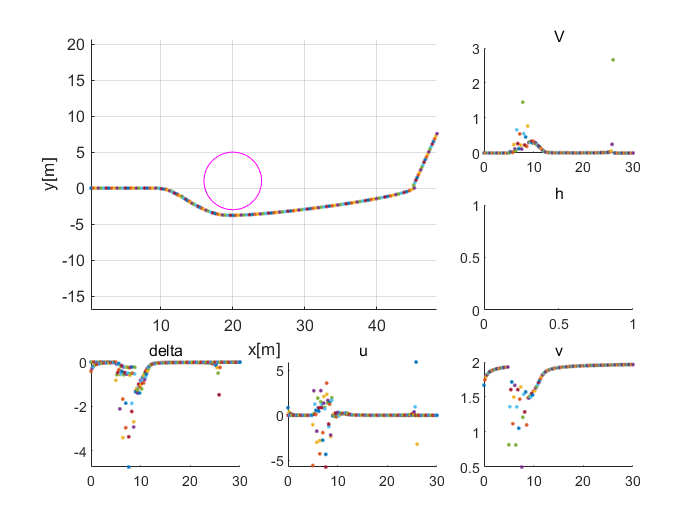

clc,clear

T=30;   %仿真时间[s]
dt=0.2;  %仿真步长

%参数
lambda=4;     %clf1比例系数
gamma=5;        %clf2比例系数

x=[0;0;1.5;0];   %初始值
u_ref=[0,0];        %期望输入
H=diag([1 1 4 2]);
%坐标图

subplot(3,3,[1 2 4 5])
B=[20;1];Br=4;
rectangle('Position',[B(1)-Br,B(2)-Br,2*Br,2*Br],'Curvature',[1,1],'EdgeColor','m'); %禁行区
xlabel('x[m]')
ylabel('y[m]')
grid on,hold on,axis equal

subplot(3,3,3),title('V')
subplot(3,3,6),title('h')
subplot(3,3,7),title('delta')
subplot(3,3,8),title('u')
subplot(3,3,9),title('v')
for t=0:dt:T
    [f,g]=cal_system(x);
%     [a,] = cal_cbf(x);
    [V1,V2,LfV1,LgV1,LfV2,LgV2] = cal_clf(x);
    [u,delta]=QP_solve(x,lambda,gamma,u_ref,[-10 10;-10 10],H);      
    x=(f+g*u).*dt+x;
    
    
    
    %画图
    subplot(3,3,[1 2 4 5]),hold on
    plot(x(1),x(2),'.'),hold off
    
    subplot(3,3,3),hold on
    plot(t,V1,'.'),hold off
    
%     subplot(3,3,6),hold on
%     plot(t,h,'.'),hold off
    subplot(3,3,7),hold on
    plot(t,delta,'.'),hold off
    subplot(3,3,8),hold on
    plot(t,u,'.'),hold off
    subplot(3,3,9),hold on
    plot(t,x(3),'.'),hold off
end